**Laborator 6 - Interpolare Lagrange**

PROBLEME

P1. Implementați o rutină pentru calculul valorilor polinomului de interpolare Lagrange când se dau punctele, nodurile și valorile funcției în noduri.

fprintf("Interpolare Lagrange:");

Interpolare Lagrange:

x = 1.001;
fprintf("f(%f) = %f", x, interpolare_Lagrange([1 2 3], [4 5 6], x));

f(1.001000) = 4.001000

P2. Reprezentați grafic polinoamele fundamentale când se dau gradul și nodurile.

fprintf("Reprezentarea grafică:");

Reprezentarea grafică:

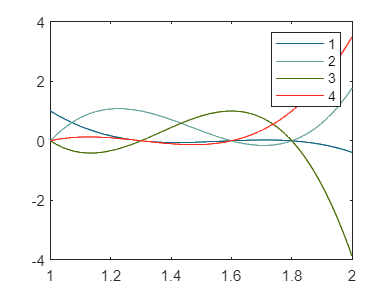

nodes = [1 1.3 1.6 1.8];
m = 4;

labels = {};
for k = 1 : m
    t = 1 : 0.01 : 2;
    p = evaluate_polynomial_multiple_points(nodes, k, t);
    labels = [labels num2str(k)];
    plot(t, p, 'color', rand(1,3))
    hold on;
end
legend(labels);
hold off;

P3. Reprezentați pe același grafic f și Lmf.

fprintf("Reprezentarea grafică a f și Lmf (sin(x)):");

Reprezentarea grafică a f și Lmf (sin(x)):

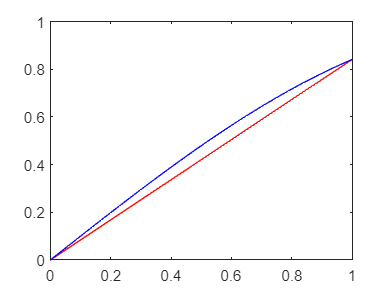

nodes = [0, 1];
nodevals = sin(nodes);

points = 0 : 0.01 : 1;
result = interpolare_Lagrange_multiple_points(nodes, nodevals, points);

plot(points, result, 'r');
hold on;

sin_result = sin(points);
plot(points, sin_result, 'b');
hold off;

P4. Dându-se x, f, m și nodurile, aproximați f(x) utilizând interpolarea Lagrange.

fprintf("Interpolare Lagrange pentru f(x) = sin(x):");

Interpolare Lagrange pentru f(x) = sin(x):

fprintf("%f", interpolare_Lagrange_known_function(1.2, @sin, 3, [1.1 1.4 1.6]));

0.932362

P5. Implementați metoda baricentrică.

fprintf("Interpolare Lagrange baricentrică:");

Interpolare Lagrange baricentrică:

x = 1.001;
fprintf("f(%f) = %f", x, interpolare_Lagrange_baricentrica([1 2 3], [4 5 6], x));

f(1.001000) = 4.001000

PROBLEME PRACTICE

P1. Aproximați populația SUA n 1975 și 2018.

% Pentru 1975:
x = [1900 1910 1920 1930 1940 1950 1960 1970 1980];
y = [75995 91972 105711 123203 131669 150697 179323 203212 226505];

fprintf("Populația SUA în anul 1975:");

Populația SUA în anul 1975:

fprintf("%f", interpolare_Lagrange_baricentrica(x, y, 1975));

215759.805115


% Pentru 2018:
x = [1990 2000 2010];
y = [249633 281422 308786];

fprintf("Populația SUA în anul 2018:");

Populația SUA în anul 2018:

fprintf("%f", interpolare_Lagrange_baricentrica(x, y, 2018));

327491.200000

P2. Fie f dat. Aproximați f(1.25) utilizând valorile lui f în 1.1, 1.2, 1.3 și 1.4 și dați o delimitare a erorii.

f = @(x)exp(x.^2 - 1);
x = 1.25;
fprintf("f(%f) = %f", x, interpolare_Lagrange_known_function(x, f, 4, [1 1.1 1.2 1.3 1.4]));

f(1.250000) = 1.755675

fprintf("!!f(%f) = %f", x, exp(x.^2 - 1));

!!f(1.250000) = 1.755055

P3. Aproximați sqrt(115) cu 3 zecimale exacte prin interpolare Lagrange.

fprintf("Aproximarea sqrt(115):");

Aproximarea sqrt(115):

x = 115;
fprintf("f(%f) = %f", x, interpolare_Lagrange_known_function(x, @sqrt, 4, [100 107 117 121]));

f(115.000000) = 10.723809

fprintf("sqrt(%f) = %f", x, sqrt(x));

sqrt(115.000000) = 10.723805

P4.

fprintf("Reprezentarea grafică a f și interpolarea lui F:");

Reprezentarea grafică a f și interpolarea lui F:

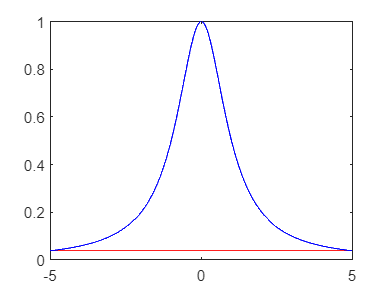

nodes = [-5, 5];
nodevals = 1./(1+nodes.*nodes);

points = -5 : 0.01 : 5;
result = interpolare_Lagrange_multiple_points(nodes, nodevals, points);

plot(points, result, 'r');
hold on;

res = 1./(1+points.*points);
plot(points, res, 'b');
hold off;

fprintf("Reprezentarea grafică a f si g:");

Reprezentarea grafică a f si g:

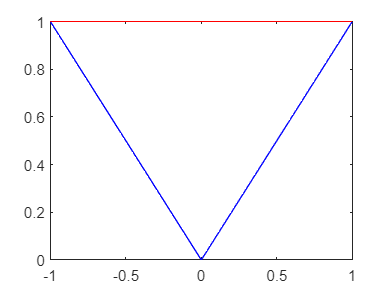

nodes = [-1, 1];
nodevals = abs(nodes);

points = -1 : 0.01 : 1;
result = interpolare_Lagrange_multiple_points(nodes, nodevals, points);

plot(points, result, 'r');
hold on;

res = abs(points);
plot(points, res, 'b');
hold off;